# Pb5

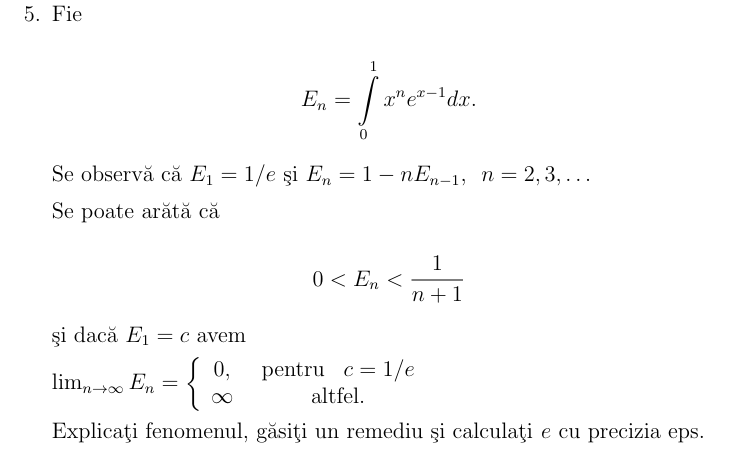

Relatia de recurență $E_n =1-{\textrm{nE}}_{n-1}$este numeric **instabila**, deoarece eroarea de la fiecare pas este amplificata de factorul n. Chiar si o eroare mica in $E_1$ (de ordinul eps) duce la valori complet eronate pentru $E_{\;n\;}$cand n creste.

**Solutia** ar fi sa ne folosim de integrala, este un mediu mai **stabil** deoarece nu avem nevoie de valoarea anterioara pentru a calcula.

N = 40;                          


E_corect = zeros(1, N);
E_corect(1) = 1 / exp(1);  % valoare exacta
for n = 2:N
    E_corect(n) = 1 - n * E_corect(n - 1);
end



E_gresit = zeros(1, N);
E_gresit(1) = 1 / exp(1) + 0.00025;  % eroare introdusa
for n = 2:N
    E_gresit(n) = 1 - n * E_gresit(n - 1);
end


E_integ = zeros(1, N);
for n = 1:N
    f = @(x) x.^n .* exp(x - 1);        % definim functia f_n(x)
    E_integ(n) = integral(f, 0, 1);     % calculam integrala
end


fprintf('n\tE_corect\tE_gresit\tE_integ\n');

n	E_corect	E_gresit	E_integ


for n = 1:N
    fprintf('%d\t%.4e\t%.4e\t%.4e\n', n, E_corect(n), E_gresit(n), E_integ(n));
end

1	3.6788e-01	3.6813e-01	3.6788e-01
2	2.6424e-01	2.6374e-01	2.6424e-01
3	2.0728e-01	2.0878e-01	2.0728e-01
4	1.7089e-01	1.6489e-01	1.7089e-01
5	1.4553e-01	1.7553e-01	1.4553e-01
6	1.2680e-01	-5.3198e-02	1.2680e-01
7	1.1238e-01	1.3724e+00	1.1238e-01
8	1.0093e-01	-9.9791e+00	1.0093e-01
9	9.1612e-02	9.0812e+01	9.1612e-02
10	8.3877e-02	-9.0712e+02	8.3877e-02
11	7.7352e-02	9.9793e+03	7.7352e-02
12	7.1773e-02	-1.1975e+05	7.1773e-02
13	6.6948e-02	1.5568e+06	6.6948e-02
14	6.2731e-02	-2.1795e+07	6.2732e-02
15	5.9034e-02	3.2692e+08	5.9018e-02
16	5.5459e-02	-5.2307e+09	5.5719e-02
17	5.7192e-02	8.8922e+10	5.2771e-02
18	-2.9454e-02	-1.6006e+12	5.0120e-02
19	1.5596e+00	3.0411e+13	4.7723e-02
20	-3.0192e+01	-6.0823e+14	4.5545e-02
21	6.3504e+02	1.2773e+16	4.3557e-02
22	-1.3970e+04	-2.8100e+17	4.1736e-02
23	3.2131e+05	6.4630e+18	4.0062e-02
24	-7.7114e+06	-1.5511e+20	3.8517e-02
25	1.9279e+08	3.8778e+21	3.7086e-02
26	-5.0124e+09	-1.0082e+23	3.5758e-02
27	1.3534e+11	2.7222e+24	3.4523e-02
28	-3.7894e+12	-7.622



e_estim = 1 / E_integ(1);
e_real = exp(1);
fprintf('\nEstimare a lui e din E_1 (prin integrare): %.20f\n', e_estim);


Estimare a lui e din E_1 (prin integrare): 2.71828182845904553488


fprintf('Valoare reala a lui e                    : %.20f\n', e_real);

Valoare reala a lui e                    : 2.71828182845904509080


fprintf('Eps                                      : %.20f\n' , eps(1));

Eps                                      : 0.00000000000000022204


fprintf('Eroare absoluta                          : %.20e\n', abs(e_estim - e_real));

Eroare absoluta                          : 4.44089209850062616169e-16


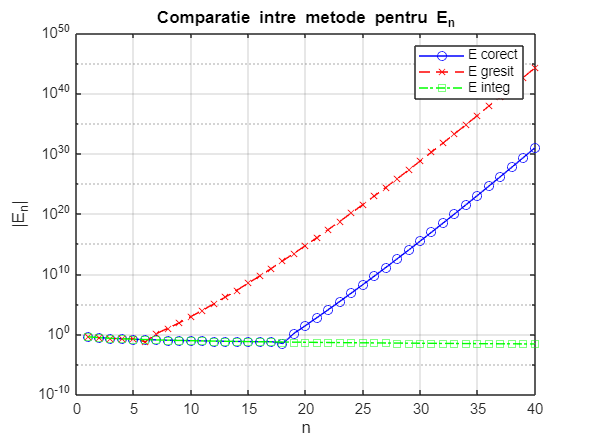



figure;
semilogy(1:N, abs(E_corect), 'b-o', 'DisplayName', 'E corect');
hold on;
semilogy(1:N, abs(E_gresit), 'r--x', 'DisplayName', 'E gresit');
semilogy(1:N, abs(E_integ), 'g-.s', 'DisplayName', 'E integ');

xlabel('n'); ylabel('|E_n|');
title('Comparatie intre metode pentru E_n');
legend;
grid on;